Aufgabe 7)

3.

clear;
x = rand(1,100) + 1i*rand(1,100);

4.

if (sum(abs(x - idft(dft(x)))) < 10e-10)
    disp("Die Singale sind identisch!");
end

Die Singale sind identisch!


5.

if (sum(abs(x - idft(fft(x)))) < 10e-10)
    disp("Die Singale sind identisch!");
end

Die Singale sind identisch!


if (sum(abs(x - ifft(dft(x)))) < 10e-10)
    disp("Die Singale sind identisch!");
end

Die Singale sind identisch!


if (sum(abs(x - ifft(fft(x)))) < 10e-10)
    disp("Die Singale sind identisch!");
end

Die Singale sind identisch!


6.

tic;
fft(x);
toc;

Elapsed time is 0.004227 seconds.


tic;
dft(x);
toc;

Elapsed time is 0.009182 seconds.


x = rand(1,10000) + 1i*rand(1,10000);
tic;
fft(x);
toc;

Elapsed time is 0.009606 seconds.


tic;
dft(x);
toc;

Elapsed time is 18.356981 seconds.


Aufgabe 8)

f1 = 40;        % [Hz]
f2 = 60;        % [Hz]

t = 0 : 1 / 100 : 1;
x1 = cos(2*pi*f1*t);
x2 = cos(2*pi*f2*t);

a1 = fft(x1 + x2);
b1 = fft(x1) + fft(x2);
if ((a1 - b1) < 10e-10)
    disp("Die Aussage ist wahr!");
end

Die Aussage ist wahr!



x3 = cos(2*pi*f1*(t + (pi / 3)));
a2 = fft(x3);

w1 = 2*pi*f1;
b2 = fft(x1) * exp(1i.*w1.*(pi/3));

if((a2 - b2) < 10e-10)
    disp("Die Aussage ist wahr!");
end

Aufgabe 9)

1.

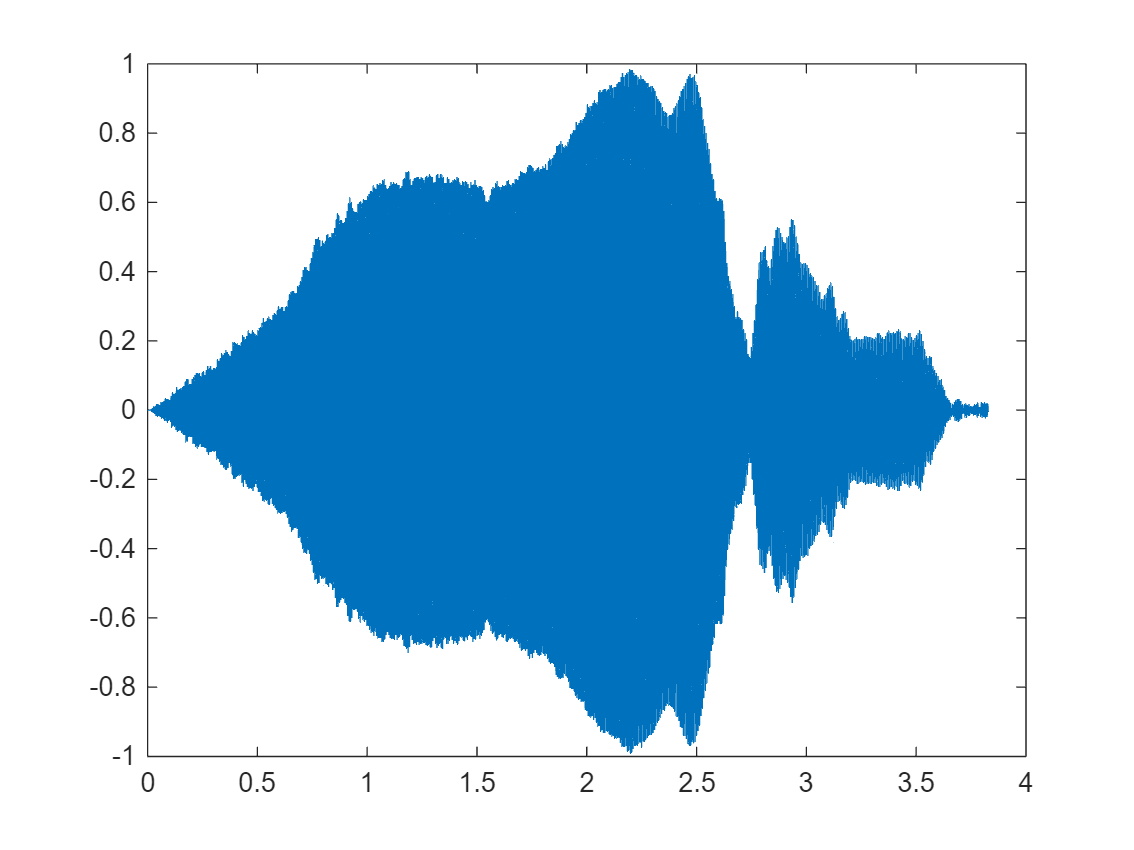

[y,Fs] = audioread("blue2ok1.mp3") ; 
x = (1:length(y)) /Fs ; 
plot(x,y);

2.

sound(y,Fs);

3.